clear all
load ARTEMIS.mat;
load ARTEMIS_road.mat
load WLTC.mat
load eff_interpol.mat
my_cycle(1,:)=linspace(30,0,1001);
my_cycle(2,:)=[my_cycle(1,1:end-1)-my_cycle(1,2:end),0];
my_cycle(3,:)=3;

start=0;%Definisci l'istante iniziale
N=5; %Time horizon
u=[];
%eff_int();
%definisci le opzioni per l'optimisation
opts=optimoptions('fmincon','MaxFunctionEvaluations',1e3,...
    'Algorithm','sqp','ConstraintTolerance',1e-3,'Display','none','FiniteDifferenceType','forward');
    
SOC=0.55*ones(1,N);
u_n=1*ones(1,N);
N_rounds=1;
N_it=1000;
u=zeros(1,N_it*N_rounds);
x=zeros(N_rounds,1);
driving_cycle=ARTEMIS;
tic
for k=1:N_rounds
     %Se si vuole cambiare ciclo tra un round e l'altro
     %x(k)=rand;
     %driving_cycle=(x(k)<0.33)*ARTEMIS+(x(k)>=0.33)*ARTEMIS_road*(x(k)<=0.66)+(x(k)>0.66)*my_cycle;
    for j=1:N_it-N
        %Estrai i sottovettori e ridefinisci gli handle per i sottovettori.
        %Stavolta la funzione di costo è calcolata tutta in una volta. Bisogna
        %rivedere la funzione di costo bene
       
        speed=driving_cycle(1,start+j:start+N-1+j);
        acceleration=driving_cycle(2,start+j:start+N-1+j);
        gear=driving_cycle(3,start+j:start+N-1+j);
        
        StateUpdate=@(input,cur_SOC,i)my_hev(speed(i),acceleration(i),gear(i),cur_SOC,input,F1,F2);
        FullStateUpdate=@(u)full_horizon(u,SOC(2),StateUpdate);
        nonlinconstr_h=@(u)nonlinconstr(u,SOC(2),StateUpdate);
        %calcoli la u ottima sull'orizzonte dei 5 secondi
        %tic
        [u_n,fin_cost(j),exitf(j),output(j)]=fmincon(FullStateUpdate,[u_n(2:end),mean(u_n)],[],[],[],[],...
            -1*ones(N,1),ones(N,1),nonlinconstr_h,opts);
        if exitf(j)<=0
            [u_n,fin_cost(j),exitf(j),output(j)]=fmincon(FullStateUpdate,[u_n(2:end),0],[],[],[],[],...
            -1*ones(N,1),ones(N,1),nonlinconstr_h,opts);
        end
        %toc
        %salvi la u per poi vedere il risultato complessivo
        u(j+(k-1)*N_it)=u_n(1);
        if exitf(j)<=0
            fprintf("All'iterazione %d l'exitflag è %d ",j,exitf(j))
        end
    
        if rem(j,N_it/10)==0
            fprintf("Siamo al: %f percento dell'iterazione %d \n Ci ha messo %f \n",j/(N_it)*100,k,toc)
            tic
        end
    
        [~,SOC]=FullStateUpdate(u_n);
    end
end

Siamo al: 10.000000 percento dell'iterazione 1 
 Ci ha messo 4.888466 
Siamo al: 20.000000 percento dell'iterazione 1 
 Ci ha messo 4.434771 
Siamo al: 30.000000 percento dell'iterazione 1 
 Ci ha messo 4.231293 
Siamo al: 40.000000 percento dell'iterazione 1 
 Ci ha messo 8.702151 
Siamo al: 50.000000 percento dell'iterazione 1 
 Ci ha messo 6.851103 
Siamo al: 60.000000 percento dell'iterazione 1 
 Ci ha messo 3.831797 
Siamo al: 70.000000 percento dell'iterazione 1 
 Ci ha messo 1.458727 
Siamo al: 80.000000 percento dell'iterazione 1 
 Ci ha messo 3.187873 
Siamo al: 90.000000 percento dell'iterazione 1 
 Ci ha messo 2.135157 


toc

Elapsed time is 7.537689 seconds.


%Vedi i risultati utilizzando la u trovata nell'intero orizzonte
speed=[];
acceleration=[];
gear=[];
j=995;

for i=1:54
    driving_cycle=(x(i)<0.33)*ARTEMIS+(x(i)>=0.33)*ARTEMIS_road*(x(i)<=0.66)+(x(i)>0.66)*my_cycle;
    speed=[speed,driving_cycle(1,start+1:start+N+j)];
    acceleration=[acceleration,driving_cycle(2,start+1:start+N+j)];
    gear=[gear,driving_cycle(3,start+1:start+N+j)];
end
StateUpdate=@(input,cur_SOC,i)my_hev(speed(i),acceleration(i),gear(i),cur_SOC,input,F1,F2);
FullStateUpdate=@(u)full_horizon(u,0.55,StateUpdate);
[cost,SOC,T_req,T_giv,mf,I_c,V_c,Tm]=FullStateUpdate(u);
[c,ceq]=nonlinconstr(u,0.55,StateUpdate);
tot_c=sum(sum(c<=0))/(4*length(c))

tot_c = 0.9990

tot_ceq=sum(abs(ceq)<=opts.ConstraintTolerance)/length(ceq)

tot_ceq = 1.0000

tot_mf=sum(mf)

tot_mf = 17.2392

tot_soc_var=SOC(1)-SOC(end)

tot_soc_var = -0.0418

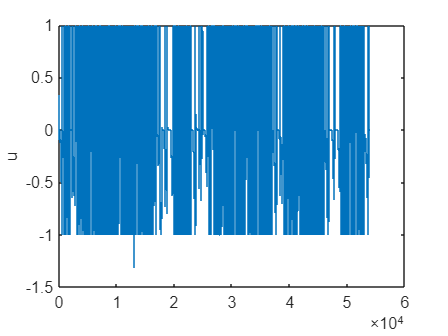


stairs(u)
ylabel('u')

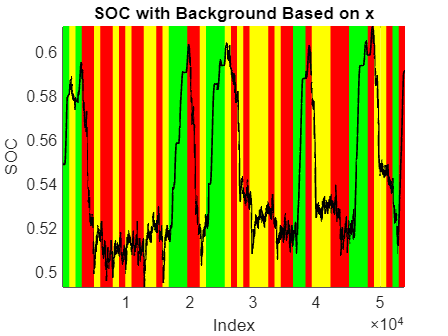

figure
hold on
num_segments = length(x); % Number of regions
segment_size = length(SOC) / num_segments; % Elements per segment
colors = [1 1 0; 1 0 0; 0 1 0]; % Define colors (red, green, blue)

for i = 1:num_segments
    % Define segment range
    x_start = (i - 1) * segment_size + 1;
    x_end = i * segment_size;
    
    % Determine background color based on x(i)
    if x(i) < 0.33
        bg_color = colors(1, :); % Light red
    elseif x(i) < 0.66
        bg_color = colors(2, :); % Light green
    else
        bg_color = colors(3, :); % Light blue
    end
    
    % Plot background as a filled rectangle
    fill([x_start x_end x_end x_start], [min(SOC) min(SOC) max(SOC) max(SOC)], ...
        bg_color, 'EdgeColor', 'none');
end

% Plot the SOC data on top
plot(SOC, 'k', 'LineWidth', 1);

% Additional plot settings
xlim([1, length(SOC)]);
ylim([min(SOC), max(SOC)]);
xlabel('Index');
ylabel('SOC');
title('SOC with Background Based on x');
box on;
hold off

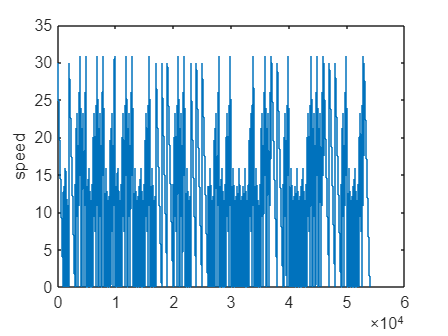


stairs(speed)
ylabel('speed')

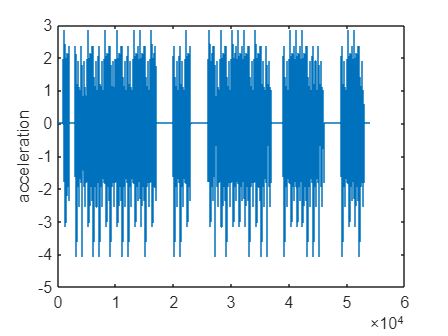

stairs(acceleration)
ylabel('acceleration')

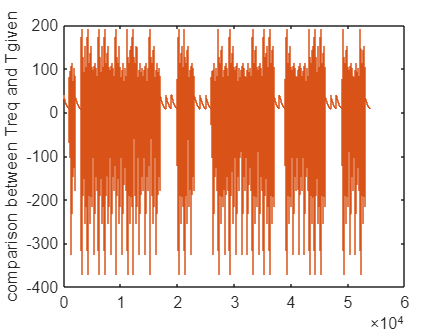

stairs(T_giv)
hold on
stairs(T_req)
hold off
ylabel('comparison between Treq and Tgiven')